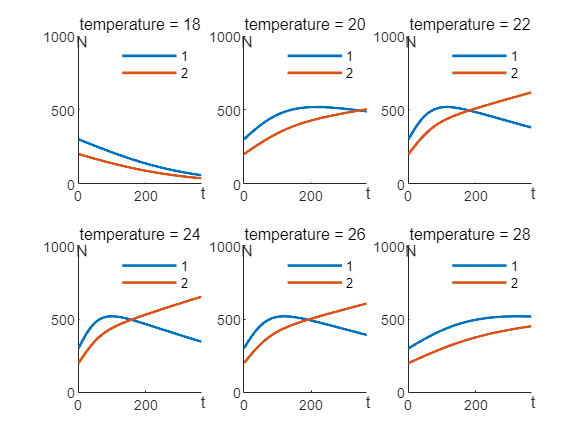

clear;clc;
%数据加载
losData = readmatrix("data\data_12_22.CSV");
losData(:,1) = smoothdata(losData(:,1));
losData(:,2) = smoothdata(losData(:,2));
pT = load("data\pT.mat").pT;
pU = load("data\pU.mat").pU;
%加载完成

% %参数说明
%
% %T为温度，U为湿度，R为降水量
% count = 3;%物种数量
% %物种一的特征：            %物种二的特征：
%     %适宜湿度范围：56.6:73.251   55:75
%     %适宜温度范围：16:23       12:22
% 
% %r的参数矩阵，第i行为第i个物种 r = k*((c1*U^2+c2*U)/(c3+U)^2+c4)*(a*T^3+b*T^2+c*T+d)*k1;
%             %lim,   c1,    c2,    c3, c4,  lim,  a,    b,  c,    d,     k,   k1
% alpha =     [%50.3,-3980,127000, 90, -65, 43.6,0.06, 1.86, -2, -43, 0.001,0.0016;
%              62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%              62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%              62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% %K的常数矩阵，第j列为第j个物种的环境容纳量常数，K(i) = beta(i);
% beta = [1000,1000,1000];
% %竞争系数 第i行j列的系数为 j物种对i物种的竞争系数，其中对角线为种内竞争 值1
% %a 2对1的竞争系数 %b 3对1的竞争系数 %c 3对2的竞争系数
% %a=0.5;b=10;c=b/a;
% a=0.5;b=1.1;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% %初始数量
% N0 = [200,300,200];
% %自变量范围
% tspan = [1,365]

%%参数：

%% ----------------------------------------------------------------%
% %onlyT
% only = "T";
% count = 3;
% alpha = [62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% beta = [1000,1000,1000];
% a=0.5;b=1.1;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [200,300,200];
% tspan = [1,365];
% 
% ylabel("N","Position",[10,650],"Rotation",pi/2);
% xlabel("t","Position",[360,0]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);
% %----------------------------------------------------------------%
%%onlyU
% only = "U";
% count = 3;
% alpha = [62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% beta = [1000,1000,1000];
% a=0.5;b=1.1;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [200,300,200];
% tspan = [1,365];

% ylabel("N","Position",[10,475],"Rotation",pi/2);
% xlabel("t","Position",[370,60]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);
%% -----------------------------------------------------------------%
%%onlyTU
% only = "TU";
% count = 3;
% alpha = [62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% beta = [1000,1000,1000];
% a=0.5;b=1.1;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [200,300,200];
% tspan = [1,365];

% ylabel("N","Position",[10,345],"Rotation",pi/2);
% xlabel("t","Position",[370,165]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);

%% ----------------------------------------------------------------- %
%%onlyTU -- 多样性 -干旱 3种 干旱一次，无反馈调节时的图像
% lowU = load("data\lowUData.mat").data;
% lowU = smoothdata(lowU);
% losData(:,2) = GDD_U(40,60,1);
% 
% only = "TU";
% count = 3;
% alpha = [65,-3050, 50000, 570,  2,  16.475,-0.02, -0.45, 3.5, 1.9, 0.004 ,0.010;
%          68,   1000, 10000 , 1100, -0.2,  16.475,-0.02, -0.45, 3.5, 1.9, -0.05  ,0.010;
%          62,   340,   0,   324  , -1.6,  16.475,-0.02, -0.45, 3.5, 1.9, -0.005 ,0.010];
% beta = [1000,1000,1000];
% a=0.8;b=0.8;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [160,140,120];
% tspan = [1,365];
% fbNum = [1,1,1;
%          1,1,1];%反馈参数
% 
% ylabel("N","Position",[10,190],"Rotation",pi/2);
% xlabel("t","Position",[370,10]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only,fbNum),tspan,N0,1);
%% --------------------------------------------------------
%%onlyTU -- 多样性 -干旱 3种 干旱一次，有反馈调节时的图像
% lowU = load("data\lowUData.mat").data;
% lowU = smoothdata(lowU);
% losData(:,2) = GDD_U(40,60,1);
% 
% only = "TU";
% count = 3;
% alpha = [65,-3050, 50000, 570,  2,  16.475,-0.02, -0.45, 3.5, 1.9, 0.004 ,0.010;
%          68,   1000, 10000 , 1100, -0.2,  16.475,-0.02, -0.45, 3.5, 1.9, -0.05  ,0.010;
%          62,   340,   0,   324  , -1.6,  16.475,-0.02, -0.45, 3.5, 1.9, -0.005 ,0.010];
% beta = [1000,1000,1000];
% a=0.8;b=0.8;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [160,140,120];
% tspan = [1,365];
% fbNum = [1,1,1;
%          30,20,20];%反馈参数
% 
% ylabel("N","Position",[10,270],"Rotation",pi/2);
% xlabel("t","Position",[360,130]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only,fbNum),tspan,N0,1);
%% ------------------------------------------------------------
%%onlyTU -- 多样性 -干旱 1种 干旱1次，有无反馈调节时的图像
% lowU = load("data\lowUData.mat").data;
% lowU = smoothdata(lowU);
% losData(:,2) = GDD_U(40,60,1);
% 
% only = "TU";
% count = 1;
% alpha =  [68,   1000, 10000 , 1100, -0.2,  16.475,-0.02, -0.45, 3.5, 1.9, -0.05  ,0.010;];
% beta = 1000;
% gamma = 1;
% N0 = 160;
% tspan = [1,365];
% for i = 1:2
%     if i == 1
%         fbNum = [1;1];%反馈参数
%     else
%         fbNum = [1;5];
%     end
%     ylabel("N","Position",[10,240],"Rotation",pi/2);
%     xlabel("t","Position",[360,50]);
%     xlim([0,tspan(2)])
%     ylim([50,250])
%     [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only,fbNum),tspan,N0,1);
%     %运行：
%     hold on
% 
%     for j = 1:count
%         plot(t,N(j,:),"LineWidth",1.5);
%     end
% 
% end
% hold off
% legend("1-noFB","1-isFB")
% legend("boxoff")
%% ---------------------------------------------------------- 
%%onlyTU -- 多样性 -干旱 3种 干旱3/4次，有反馈调节时的图像
% lowU = load("data\lowUData.mat").data;
% lowU = smoothdata(lowU);
% losData(:,2) = GDD_U(40,60,4);
% 
% only = "TU";
% count = 3;
% alpha = [65,-3050, 50000, 570,  2,  16.475,-0.02, -0.45, 3.5, 1.9, 0.004 ,0.010;
%          68,   1000, 10000 , 1100, -0.2,  16.475,-0.02, -0.45, 3.5, 1.9, -0.05  ,0.010;
%          62,   340,   0,   324  , -1.6,  16.475,-0.02, -0.45, 3.5, 1.9, -0.005 ,0.010];
% beta = [1000,1000,1000];
% a=0.1;b=0.8;c=b/a;
% gamma = [1,  a,  b; 
%          1/a,  1, c ;
%          1/b, 1/c, 1];
% N0 = [160,140,120];
% tspan = [1,365];
% fbNum = [1,1,1;
%          10,10,10];%反馈参数
% 
% ylabel("N","Position",[10,240],"Rotation",pi/2);
% xlabel("t","Position",[360,10]);
% xlim([0,tspan(2)])
% [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only,fbNum),tspan,N0,1);
%%-------------------------------------------------------%
%%onlyTU -- 灵敏度测试K值
% only = "TU";
% count = 2;
% alpha = [62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%          62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% 
% a=0.01;
% gamma = [1,  a,  ; 
%          1/a,  1, ];
% N0 = [20,30];
% tspan = [1,365];
% for k = [1000,2000,3000]
%     beta = [k,k];
% 
%     [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);
% 
% 
%     subplot(1,3,k/1000);
%     hold on
%     for i = 1:count
%         plot(t,N(i,:),"LineWidth",1.5);
%     end
%     ylim([0,90]);
%     xlim([0,tspan(2)])
%     title("K = "+mat2str(k));
%     ylabel("N","Position",[10,87],"Rotation",pi/2);
%     xlabel("t","Position",[370,3]);
%     legend("1","2")
%     legend("boxoff")
%     hold off
% end
%% -------------------------------------------------------% 
%%onlyU -- 灵敏度测试 湿度 55 60 65 70
% only = "U";
% num = 1;
% for z = [54 58 62 66 70 74 ]
%     losData(:,2) = z*ones(size(losData(:,2)));
%     count = 2;
%     alpha = [62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010;
%              62.5,-4200, 16200, 154, 16,  16.475,-0.02, -0.45, 3.5, 1.9, 0.0015,0.010];
% 
%     a=0.1;
%     gamma = [1,  a,  ; 
%              1/a,  1, ];
%     N0 = [20,30];
%     tspan = [1,365];
%     beta = [1000,1000];
%     [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);
%     subplot(2,3,num);
%     num = num+1;
% hold on
% for i = 1:count
%     plot(t,N(i,:),"LineWidth",1.5);
% end
% ylim([0,90]);
% xlim([0,tspan(2)])
% title("humidity = "+mat2str(z));
% ylabel("N","Position",[10,87],"Rotation",pi/2);
% xlabel("t","Position",[370,3]);
% legend("1","2")
% legend("boxoff")
% hold off
% end
%% ------------------------------------------------------% 
%%onlyT -- 灵敏度测试 温度 0 10 20 30 40
only = "T";
num = 1;
for z = [18 20 22 24 26 28]
    losData(:,1) = z*ones(size(losData(:,1)));
    count = 2;
    alpha = [62.5,-4200, 16200, 154, 16,  11.6,  -0.0028, -0.05, 2.5, -14, 0.0015,0.008;
             62.5,-4200, 16200, 154, 16,  11.6,  -0.0028, -0.05, 2.5, -14, 0.0015,0.008];

    a=1.1;
    gamma = [1,  a,  ; 
             1/a,  1 ];
    N0 = [300,200];
    tspan = [1,365];
    beta = [1000,1000];
    [t,N] = ODE4(@(t,N)lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only),tspan,N0,1);


    subplot(2,3,num);
    num = num+1;
hold on
for i = 1:count
    plot(t,N(i,:),"LineWidth",1.5);
end
ylim([0,1000]);
xlim([0,tspan(2)])
title("temperature = "+mat2str(z));
ylabel("N","Position",[10,900],"Rotation",pi/2);
xlabel("t","Position",[370,3]);
legend("1","2")
legend("boxoff")
hold off
end



%%-------------------------------------------------------%
% %运行：
% hold on
% 
% for i = 1:count
%     plot(t,N(i,:),"LineWidth",1.5);
% end
% legend("1","2","3")
% legend("boxoff")
% hold off
% 
% plot(1:tspan(2),losData(1:tspan(2),2)');
% xlabel("t","Position",[410,27]);
% ylabel("U","Position",[10,77],"Rotation",pi/2);
% ylim([25,80]);


function fun = lotkaFun(t,N,losData,pT,pU,count,alpha,beta,gamma,only,varargin)
    mid = [T(t,pT,losData);U(t,pU,losData);R(t,losData)];
    resV = zeros([count,count]);
    fun = zeros([count,1]);
    r = zeros([count,1]);
    k = zeros([count,1]);
    sumMid = zeros([count,2]);
    midResV = zeros([1,count]);
    if size(varargin) ~= 0
        fbNum = cell2mat(varargin);
        for i = 1:count
            sumMid(i,1) = sum(N(i,end)/beta(i))*fbNum(1,i);
            sumMid(i,2) = sum(N(i,end)/beta(i))*fbNum(2,i);
        end
    end

    for i = 1:count
        if size(varargin) ~= 0
            r(i) = getr(mid(1),mid(2),alpha(i,:),only,sumMid);
        else
            r(i) = getr(mid(1),mid(2),alpha(i,:),only);
        end

        %k(i) = beta(i,:)*mid; % k = aT+bU+cR
        %k(i) = r(i);
        k(i) = beta(i); %环境容纳量固定
    end    
    for i = 1:count
        midResV(1,i) = N(i)/k(i);
    end
    for i = 1:count
        resV(i,:) = gamma(i,:) .* midResV(1,:);
    end
    
    for i = 1:count
        fun(i) = r(i)*N(i)*(1-sum(resV(i,:)));
    end
end


function [r] = getr(T,U,alpha,only,varargin)
%最适温度
minU = 55 ;maxU = 70 ;%最适湿度
if size(varargin) ~=0
    sumMid = cell2mat(varargin);
    T = T+sum(sumMid(:,1));

    if U < (minU+maxU)/2
        U = U+sum(sumMid(:,2));
    else
        U = U-sum(sumMid(:,2));
    end

end

    %r的参数矩阵
            % 1  2   3 4  5  6    7 8  9  10 11 12
            %lim,c1,c2,c3,c4,lim,a, b, c, d, k,k1
%     alpha = [1,1, 1, 1, 1, 1 ,1, 1, 1, 1, 1,1]
lim=alpha(1);
c1=alpha(2);c2=alpha(3);c3=alpha(4);c4=alpha(5);
lim2=alpha(6);
a=alpha(7);b=alpha(8);
c=alpha(9);d=alpha(10);k=alpha(11);k1 = alpha(12);
if only == "T"
    r = ((a*(T-lim2)^3+b*(T-lim2)^2+c*(T-lim2)+d))*k1; %温度
elseif only == "U"
    r = k*((c1*(U-lim)^2+c2*(U-lim))/(c3+(U-lim))^2+c4);%湿度
elseif only == "TU"
    r = k*((c1*(U-lim)^2+c2*(U-lim))/(c3+(U-lim))^2+c4)*((a*(T-lim2)^3+b*(T-lim2)^2+c*T+d))*k1;%温度与湿度
end



end

function [T] = T(t,pT,losData)
    
% %拟合数据
% [year,day] = DayMap(t);
% T = polyval(pT(year,:),day);
 % 原始数据
    t = ceil(t);
   T = losData(t,1);
end

function [U] = U(t,pU,losData)

% 拟合数据
% [year,day] = DayMap(t);
% U = polyval(pU(year,:),day);
%原始数据
t = ceil(t);
U = losData(t,2);
end

function [R] = R(t,losData)
    t = ceil(t);
    R = losData(t,3);
end

function [year,day] = DayMap(t)
                %2012 2013 14   15   16  17    18   19   20   21   22
    lastDayNum = [366,732,1095,1460,1826,2191,2556,2921,3287,3652,4017];
    j=1;
    for i = lastDayNum
        if t>i
           j=j+1;
        else
           break;
        end
    end
    year = j;
    if j==1
        day = t;
    else
        day = t-lastDayNum(j-1);
    end
end

